# Supplement 3: Simulation of NMR spectra at zero and ultra-low field vs high field

Supplementary material to "Simulation of NMR spectra at zero- and ultra-low field from A to Z – a tribute to Prof. Konstantin L’vovich Ivanov" [https://doi.org/10.5194/mr-2022-18](https://doi.org/10.5194/mr-2022-18) 

*Q. Stern and K. Sheberstov*

This script shows how to simulate NMR spectra for a pair of *J*-coupled spins (1H and 13C in this example) at zero field (ZF), ultra-low field (ULF) and high field (HF). The code follows pricesely the structure of the paper.

clear all

All simulated experiments are performed at 298 K (use to compute the thermal equilibrium polarizations)

T=298;              % Temperature of prepolarization in K

Physical constants (used to compute the thermal equilibrium polarizations and the magnetic field produced by the sample in the ZULF experiments)

hbar=1.05457e-34;   % Reduced Planck constant in J.s/rad
kB=1.3806485e-23;   % Boltzmann constant J.K-1
mu0=4*pi*1e-7;      % Permeability of free space dived in T.m.A-1 
NA=6.02e23;         % Avogadro's number in mol-1

### 2.1 Define the experimental sequence

#### **ZF case**

The sample is prepolarized at 2 T (magnetic field aligned along the *z*-axis). We assume that the sample spends enough time in the prepolarizing field for the spins to be at equilibrium (Boltzmann distribution). The sample is brought suddenly to zero field, where the magnetic field generated by the sample along time is measured by a magnetometer placed along the *z*-axis and sensitive to fields along the *z*-axis. The sudden transitions projects the Zeeman states onto the basis states at ZF (the states of the coupled basis) and induce coherences between them.

Bpol=2;             % Field for prepolarization in T

#### **ULF case**

The experiment is the same as the ZF, except that a magnetic field of 50 uT is applied along the *x*-axis during detection. 

Bx=0.5e-6;          % Magnetic field along x for ULF experiments in T

#### **HF case**

Standard HF-NMR acquisition at 9.4 T where a 90° radiofrequency (rf) pulse along the *x*-axis is applied to nutate the spins from the *z*-axis to the *y*-axis. The oscillating magnetic field is recorded along the *y*-axis. The experiment is simulated both for pulse and acquisition on 1H and 13C.

B0=9.4;             % Magnetic field for HF experiments in T (typical 400 MHz magnet)

### 2.2 Define the spin system

The spin system is a pair of *J*-coupled spins. Spins I and S are a 13C and 1H spin, respectively, for all simulations.

JIS=140;            % J-coupling between spin I and S in Hz
gI= 67.262e6;       % Gyromagnetic ration of spin I (13C) in rad.s-1.T-1
gS=276.513e6;       % Gyromagnetic ration of spin S (1H) in rad.s-1.T-1

### 2.3 Compute the spin Hamiltonian

Both the ZULF and HF simulation use the same operators. Their expression is given in Sec. 2.3 of the manuscript

Pauli matrices (see Eq. 3)

e =[1 0;  0 1];
sx=[0 1;  1 0];
sy=[0 -1i;1i 0];
sz=[1 0;  0 -1];

Operators for spin I, i.e., the 13C spin (see Eq. 6)

Ix=kron(sx/2,e); 
Iy=kron(sy/2,e);
Iz=kron(sz/2,e);

Operators for spin S, i.e., the 1H spin (see Eq. 7)

Sx=kron(e,sx/2); 
Sy=kron(e,sy/2);
Sz=kron(e,sz/2);

Unity operator in the two-spin Hilbert space

E=kron(e,e);

Zeeman Hamiltonian expressed in rad.s-1 as a function of field along x, y and z in T

HZ=@(Bx, By, Bz) -gI*(Bx*Ix+By*Iy+Bz*Iz) -gS*(Bx*Sx+By*Sy+Bz*Sz);

*J*-Hamiltonian expressed in rad.s-1 (with the *J*-coupling expressed in Hz)

HJ=2*pi*JIS*(Ix*Sx+Iy*Sy+Iz*Sz);

Total Hamiltonian expressed in rad.s-1 as a function of field along x, y and z in T

Htot=@(Bx, By, Bz) HJ+HZ(Bx, By, Bz);

### 2.4 Define the initial state: compute the initial density matrix

#### ZULF case

Polarization of spin I and S at equilibrium in the prepolarizing magnet calculated using Boltzman distribution (see Eq. 22)

PI=tanh(hbar*Bpol*gI/kB/T/2);
PS=tanh(hbar*Bpol*gS/kB/T/2);

The initial state is the same for the ZF and ULF experiment (see Eq. 23)

Iz_2x2=sz/2;
rhoI=e/2+PI*Iz_2x2;
rhoS=e/2+PS*Iz_2x2;
rho_eq_ZULF=kron(rhoI,rhoS);

Modification of the density matrix removing the identity (see Eq. 24)

rho_eq_ZULF=rho_eq_ZULF-E/4;

#### HF case

The only diffrence with the ZULF case is that the magnetic field at which the spins are prepolarized is higher at HF.

Polarization of spin I and S at equilibrium in the 9.4 T NMR magnet calculated using Boltzman distribution (see Eq. 22)

PI=tanh(hbar*B0*gI/kB/T/2);
PS=tanh(hbar*B0*gS/kB/T/2);

The initial state is the same for the ZF and ULF experiment (see Eq. 23)

Iz_2x2=sz/2;
rhoI=e/2+PI*Iz_2x2;
rhoS=e/2+PS*Iz_2x2;
rho_eq_HF=kron(rhoI,rhoS);

Modification of the density matrices removing the identity (see Eq. 24)

rho_eq_HF=rho_eq_HF-E/4;

### 2.5-6 Propagate the density matrix under the Hamiltonians and extract expectation values from the propagation

In practice the expactation values are extracted from the density matrix during the progation (and not in an extra step). This avoids creating a second *for* loop.

Parameters for propagation

taq=5;              % Propagation/acquisition time in s
K=2^12;             % Number of points in the FID
L=2^16;             % Number of points in the FID with zero filling
T2=1;               % Coherence time constant in s
dt=taq/K;           % Time interval for propagation in s
t=(0:K-1)'/K*taq;   % Time axis in s

#### **ZF case**

Observable operator: total field along z in pT at distance r from the sample (in the point dipole approximation, see Eq. 34 and 35). The sample contains 27 mol-L-1 of molecules and has a volume of 100 uL. The detector is placed at 1 cm from the sample.

C=27;               % Molecule concentration in mol.L-1
V=100e-6;           % Sample volume in L
r=0.01;             % Distance between the center of the sample and the center of the detector in m
N=NA*C*V;           % Number of molecules
O=gI*Iz+gS*Sz;      % Observation operator
Constant=N*hbar*1e12*mu0/2/pi/r^3;

Propagator during time interval $\textrm{dt}$ with no field along any direction (see Eq. 30)

U =expm(-1i*dt*Htot(0,0,0));

Empty vector to store the time domain signal during the for loop

TDS_ZF=zeros(K,1);

Initialization of the density matrix

rho=rho_eq_ZULF;    

Propagation loop

Propagation loop. The first line in the loop computes the expectation value of the field along z (see Eq. 35) at time $t_k$. The second line in the loop propagates the state of the system during the interval $\textrm{dt}$, in other words, it "takes" the density matrix from time $t_k$ to $t_{k+1}$ (see Eq. 29). Note that each loop overrides the previous density matrix. The expectation value that is computed at iteration *k* corresponds to the density matrix of iteration *k-*1*. *Note that the expectation value should in principle be real-valued. However, due to the finite precision of numerical calculations, some minute imaginary part may remain when computing the trace. We therefore use the function *real()* to remove the imaginary part.

for k=1:K
    TDS_ZF(k)=Constant*real(trace(O*rho));
    rho=U*rho*U';
end

#### **ULF case**

The observable is the same as for the ZF case.

Propagator during time interval $\textrm{dt}$ with a bias field along the *x*-axis and no fields along the *y-* and *z*-axes (see Eq. 30).

U=expm(-1i*dt*Htot(Bx,0,0));

Empty vector to store the time domain signal during the for loop

TDS_ULF=zeros(K,1);

Initialization of the density matrix

rho=rho_eq_ZULF;    

Propagation loop. The first line in the loop computes the expectation value of the field along z (see Eq. 35) at time $t_k$. The process is exaclty the same as for the ZF case, except that the propagator was calculated for the ULF Hamiltonian (with a small bias field along the *x*-axis).

for k=1:K
    TDS_ULF(k)=Constant*real(trace(O*rho));
    rho=U*rho*U';
end

#### **HF case - 13C**

The observable at high field is the a operator (expressed in arbitrary units)

O=Ix-1i*Iy;

Propagator with a bias field along the *x*-axis and no fields along the *y-* and *z*-axes (see Eq. 30).

U=expm(-1i*dt*Htot(0,0,B0));

Empty vector to store the time domain signal during the for loop

TDS_HF_13C=zeros(K,1);

Initialization of the density matrix

rho=rho_eq_HF;    

The HF experiment requires simulating a pulse: the thermal equilibrium density matrix represents both the 13C and 1H spins with polarization along the *z*-axis. The rotation operator *Up* below (see the discussion following Eq. 29) is used to rotate the 13C spin from the *z*-axis to the the *y*-axis.

Up=expm(-1i*Iy*pi/2);
rho=Up*rho*Up';

Propagation loop. The first line in the loop computes the expectation value of the field along z (see Eq. 35) at time $t_k$. The second line in the loop propagates the state of the system during the interval $\textrm{dt}$, in other words, it "takes" the density matrix from time $t_k$ to $t_{k+1}$ (see Eq. 29).

for k=1:K
    TDS_HF_13C(k)=trace(O*rho);
    rho=U*rho*U';
end

#### **HF case - 1H**

The observable at high field is a shift operator (expressed in arbitrary units)

O=Sx-1i*Sy;

Propagator with a bias field along the *x*-axis and no fields along the *y-* and *z*-axes (see Eq. 30).

U=expm(-1i*dt*Htot(0,0,B0));

Empty vector to store the time domain signal during the for loop

TDS_HF_1H=zeros(K,1);

Initialization of the density matrix

rho=rho_eq_HF;    

The HF experiment requires simulating a pulse: the thermal equilibrium density matrix represents both the 13C and 1H spins with polarization along the *z*-axis. The rotation operator *Up* below (see the discussion following Eq. 29) is used to rotate the 1H spin from the *z*-axis to the the *y*-axis.

Up=expm(-1i*Sy*pi/2);
rho=Up*rho*Up';

Propagation loop. The first line in the loop computes the expectation value of the field along z (see Eq. 35) at time $t_k$. The second line in the loop propagates the state of the system during the interval $\textrm{dt}$, in other words, it "takes" the density matrix from time $t_k$ to $t_{k+1}$ (see Eq. 29).

for k=1:K
    TDS_HF_1H(k)=trace(O*rho);
    rho=U*rho*U';
end

### 2.7 Fourier transform the expectation values to obtain a spectrum

The time domain signals obained in the previous step do not decay to zero because we did not include any relaxation in the simulations, as can be seen in the plots below.

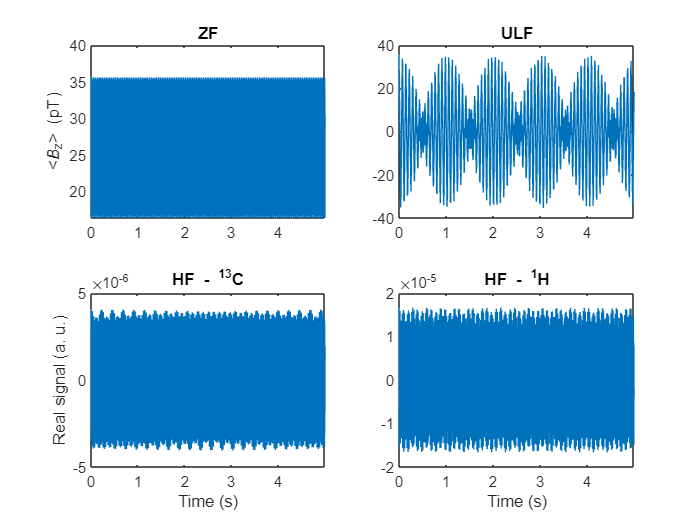

figure
subplot(2,2,1)
plot(t,TDS_ZF)
ylabel('<{\itB}_z> (pT)')
xlim([0 max(t)])
title('ZF')

subplot(2,2,2)
plot(t,TDS_ULF)
xlim([0 max(t)])
title('ULF')

subplot(2,2,3)
plot(t,real(TDS_HF_13C))
xlabel('Time (s)'), ylabel('Real signal (a. u.)')
xlim([0 max(t)])
title('HF - ^{13}C')

subplot(2,2,4)
plot(t,real(TDS_HF_1H))
xlabel('Time (s)')
xlim([0 max(t)])
title('HF - ^1H')

To make the signals decay 0, we apply an apodization function (see Eq. 37)

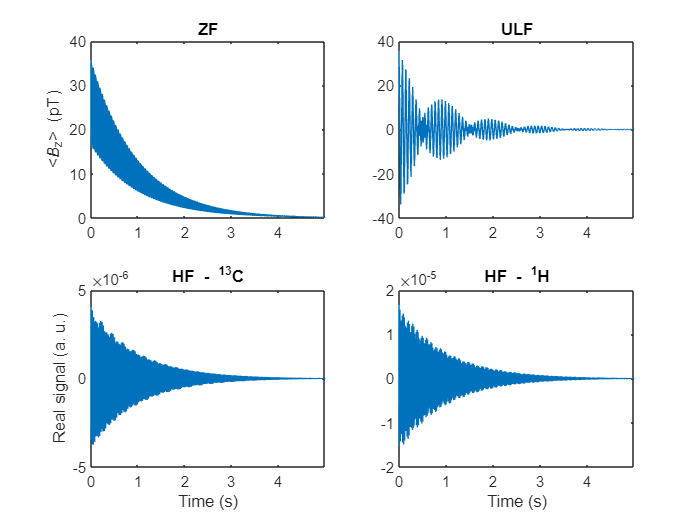

TDS_ZF2    =TDS_ZF    .*exp(-t/T2);
TDS_ULF2   =TDS_ULF   .*exp(-t/T2);
TDS_HF_13C2=TDS_HF_13C.*exp(-t/T2);
TDS_HF_1H2 =TDS_HF_1H .*exp(-t/T2);

figure
subplot(2,2,1)
plot(t,TDS_ZF2)
ylabel('<{\itB}_z> (pT)')
xlim([0 max(t)])
title('ZF')

subplot(2,2,2)
plot(t,TDS_ULF2)
xlim([0 max(t)])
title('ULF')

subplot(2,2,3)
plot(t,real(TDS_HF_13C2))
xlabel('Time (s)'), ylabel('Real signal (a. u.)')
xlim([0 max(t)])
title('HF - ^{13}C')

subplot(2,2,4)
plot(t,real(TDS_HF_1H2))
xlabel('Time (s)')
xlim([0 max(t)])
title('HF - ^1H')

A second apodization function is applied to avoid baseline distortion (see Eq. 37 and the related discussion)

TDS_ZF3    =[TDS_ZF2(1);     2*TDS_ZF2(2:end-1);    TDS_ZF2(end)];
TDS_ULF3   =[TDS_ULF2(1);    2*TDS_ULF2(2:end-1);   TDS_ULF2(end)];
TDS_HF_13C3=[TDS_HF_13C2(1); 2*TDS_HF_13C2(2:end-1);TDS_HF_13C2(end)];
TDS_HF_1H3 =[TDS_HF_1H2(1);  2*TDS_HF_1H2(2:end-1); TDS_HF_1H2(end)];

At HF, the time-domain signal must also be modulated by multiplying the time-domain signal by a complex exponential. This mathematical process is equivalent to what the spectrometer does: the NMR coil picks up a signal at oscillate at the Larmor frequency, which is much too high to be digitized. The oscillating current is therefore modulated with the carrier frequency and the modulated signal is digitized. This shifts the frequency of the oscillating signals and cause the spectrum to be centered around the carrier frequency.

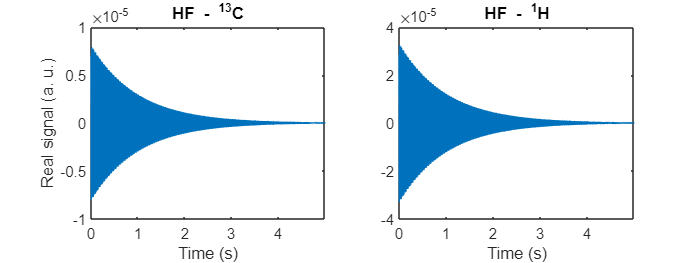

omega1=-gI*B0;
omega2=-gS*B0;
TDS_HF_13C4=TDS_HF_13C3.*exp(1i*omega1*t);
TDS_HF_1H4 =TDS_HF_1H3 .*exp(1i*omega2*t);

figure('Units','centimeters','Position',[0 0 14.8167   11.1125/2])
subplot(1,2,1)
plot(t,real(TDS_HF_13C4))
xlabel('Time (s)'), ylabel('Real signal (a. u.)')
xlim([0 max(t)])
title('HF - ^{13}C')

subplot(1,2,2)
plot(t,real(TDS_HF_1H4))
xlabel('Time (s)')
xlim([0 max(t)])
title('HF - ^1H')

Finally, the signal is Fourier transformed to obtain the frequency-domain signal. In the case of the ZULF signals, only the real part of the Fourier transform is retained. 

FDS_ZF = real(fft(TDS_ZF3,L))/L;
FDS_ULF= real(fft(TDS_ULF3,L))/L;
FDS_ZF = FDS_ZF(1:L/2);
FDS_ULF= FDS_ULF(1:L/2);

At HF, the measured signal is complex. Note that the functions *fftshift()* is used for the signals at HF because the convention that MATLAB uses for the fast Fourier transform does not places the 0 frequency on the edges. To obtain a frequency-domain as is common in NMR, the function *fftshift() *is used.

FDS_HF_13C = fftshift(fft(TDS_HF_13C4,L))/L;
FDS_HF_1H  = fftshift(fft(TDS_HF_1H4,L))/L;

The frequency axis is generated using Eq. 39 and 40. At ZULF, the time-domain signal is real (in usual cases) and so only positive frequencies are used. At HF, the time-domain signal is imaginary and so both negative and positive frequencies are used.

f=(K-1)/taq;            % Sampling frequency in Hz
nu_ZULF=(0:L/2-1)/L*f;  % Frequency axis in Hz
nu_HF=(-L/2:L/2-1)/L*f; % Frequency axis in Hz

The figure below plots the four obtained spectra. The ZF spectrum contains one line at 0 and one at the frequency of the *J*-coupling. These lines are split at ULF. Both spectra at HF have the same appearance: they consist of doublet centered on the carrier frequency (because our simulation did not include any chemical shift) with the splitting of the doublet corresponding to the frequency of the *J*-coupling. The signals on the HF 1H spectrium is 4x more intense than that of the 13C HF spectrum because of the 4x higher Boltzmann polarization of 1H spins.

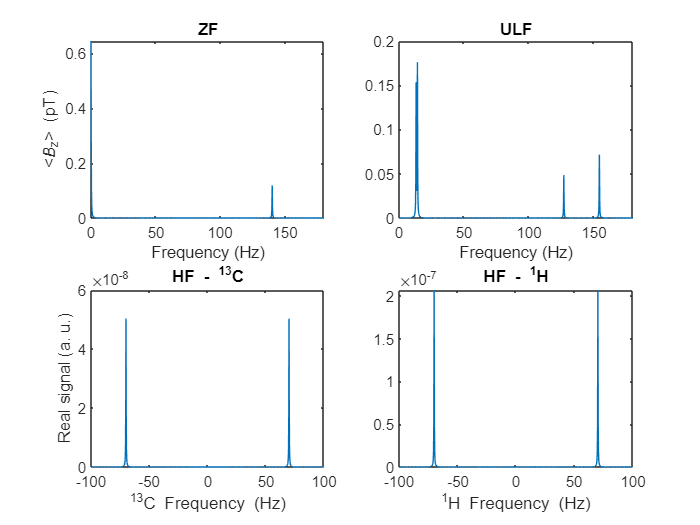

figure
subplot(2,2,1)
plot(nu_ZULF,FDS_ZF)
xlabel('Frequency (Hz)')
ylabel('<{\itB}_z> (pT)')
xlim([0 180])
title('ZF')

subplot(2,2,2)
plot(nu_ZULF,FDS_ULF)
xlabel('Frequency (Hz)')
xlim([0 180])
title('ULF')

subplot(2,2,3)
plot(nu_HF,real(FDS_HF_13C))
xlabel('^{13}C Frequency (Hz)'), ylabel('Real signal (a. u.)')
xlim([-100 100])
title('HF - ^{13}C')

subplot(2,2,4)
plot(nu_HF,real(FDS_HF_1H))
xlabel('^1H Frequency (Hz)')
xlim([-100 100])
title('HF - ^1H')